addpath('HHT_EWS')

%df_fold = csvread('HHT_EWS/traj_data.csv',1);
df_fold_long = csvread('HHT_EWS/traj_data_fold_long.csv',1);
df_foldwoNoise = csvread('HHT_EWS/traj_data_fold_woNoise.csv',1);

df_fold = df_fold_long(1:780000,:);

[imf,residual,info] = emd(df_fold(:,3),'Interpolation','pchip');

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        3     |     0.058592   |  SiftMaxRelativeTolerance
      2      |        3     |      0.10602   |  SiftMaxRelativeTolerance
      3      |        3     |       0.1113   |  SiftMaxRelativeTolerance
      4      |        3     |      0.10497   |  SiftMaxRelativeTolerance
      5      |        2     |      0.18775   |  SiftMaxRelativeTolerance
      6      |        2     |      0.11595   |  SiftMaxRelativeTolerance
      7      |        2     |     0.088254   |  SiftMaxRelativeTolerance
      8      |        2     |     0.080192   |  SiftMaxRelativeTolerance
      9      |        2     |     0.046576   |  SiftMaxRelativeTolerance
     10      |        2     |     0.061721   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


% Perform ensemble EMD
Ne = 500;
sigma_e = 0.5; % still works with sigma = 1.5
rng(50);
[m,n] = size(df_fold);

avg_trials = [];
for trial_ =1:1:Ne
    noise_ = randn(m,1).*sigma_e;
    imf_ = emd(df_fold(:,3) + noise_, 'Interpolation', 'pchip');
    
    
    % add on to running avg
    if trial_ == 1
        avg_trials = imf_;
    end
    if trial_ >1
        current_N  = trial_-1;
        avg_trials = avg_trials + imf_;        
    end
end

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030882   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061113   |  SiftMaxRelativeTolerance
      3      |        2     |     0.071195   |  SiftMaxRelativeTolerance
      4      |        2     |     0.077004   |  SiftMaxRelativeTolerance
      5      |        2     |     0.085789   |  SiftMaxRelativeTolerance
      6      |        2     |     0.093205   |  SiftMaxRelativeTolerance
      7      |        2     |     0.092684   |  SiftMaxRelativeTolerance
      8      |        2     |     0.085595   |  SiftMaxRelativeTolerance
      9      |        2     |     0.079242   |  SiftMaxRelativeTolerance
     10      |        2     |     0.080162   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.
Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030736   |  SiftMaxRelativeTolerance


imf_eemd = avg_trials./Ne;

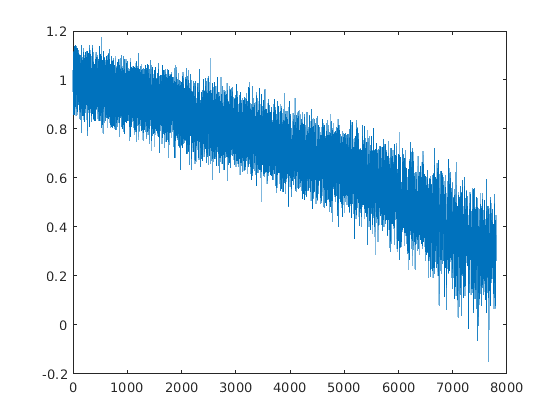

plot(df_fold(:,2), df_fold(:,3))

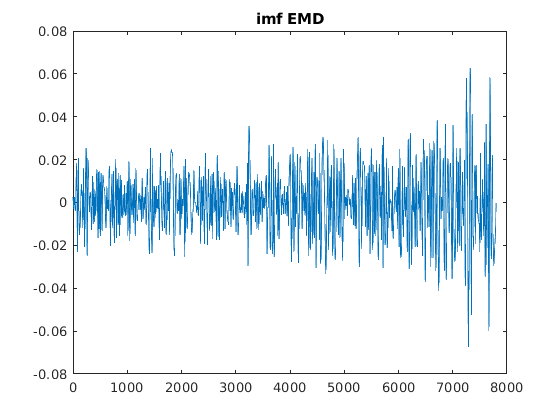

clf
plot(df_fold(:,2), imf(:,9))
title("imf EMD")

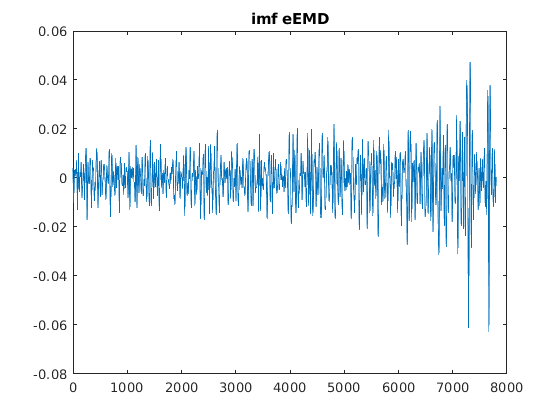

clf
plot(df_fold(:,2), imf_eemd(:,10))
title("imf eEMD")

[hs,f,t,imfinsf,imfinse] = hht(imf,100);
[hs_eemd,f_eemd,t,imfinsf_eemd,imfinse_eemd] = hht(imf_eemd,100);

%t = t(1:40000)

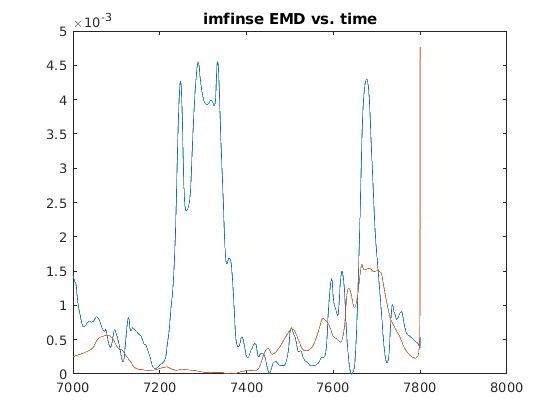

clf
plot(t, imfinse(:,9:end))
title("imfinse EMD vs. time")
xlim([7000,8000])

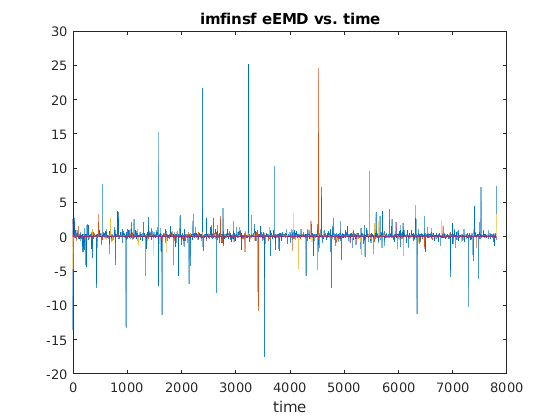

clf
plot(t, imfinsf_eemd(:,7:end))
title("imfinsf eEMD vs. time")
%xlim([350,450])
xlabel("time")

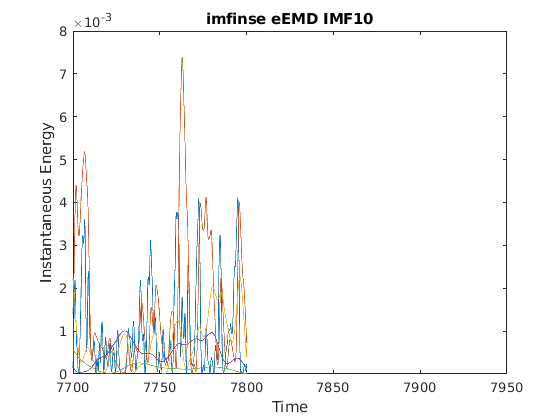

% IMF 10 has a very significant energy increase as 
% the bifurcation is approached
clf 
plot(t, imfinse_eemd(:,6:10))
title("imfinse eEMD IMF10")
xlabel("Time")
ylabel("Instantaneous Energy")
xlim([7700,7950])

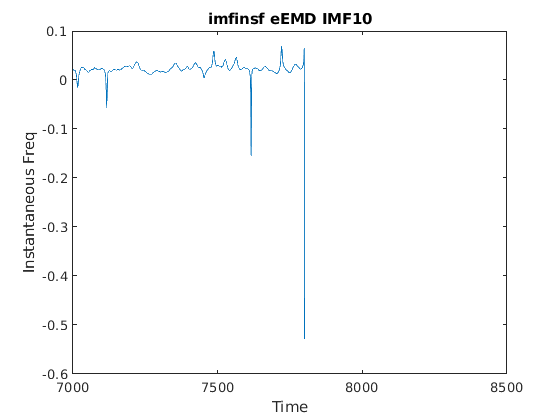

% IMF 10 has a very significant energy increase as 
% the bifurcation is approached
clf 
plot(t, imfinsf_eemd(:,10))
title("imfinsf eEMD IMF10")
xlabel("Time")
ylabel("Instantaneous Freq")
xlim([7000,8500])

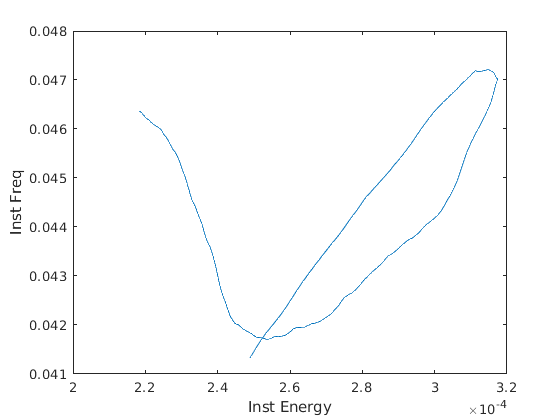

clf 
plot(imfinse_eemd(6500:7800,9), imfinsf_eemd(6500:7800,9))
ylabel("Inst Freq")
xlabel("Inst Energy")

%xlim([0,0.05])
%ylim([-1,1])

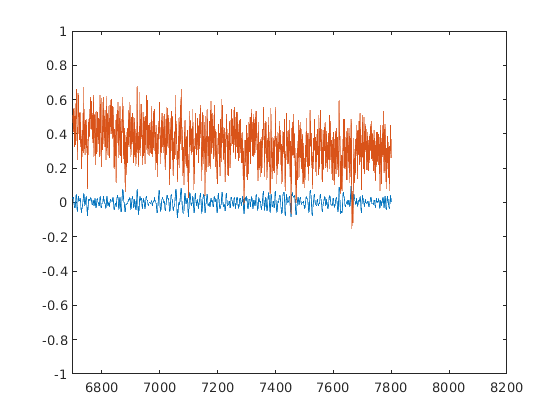

clf
plot(t, imf_eemd(:,8))
hold on
plot(t, df_fold(:,3))
xlim([6700,8200])
ylim([-1,1])

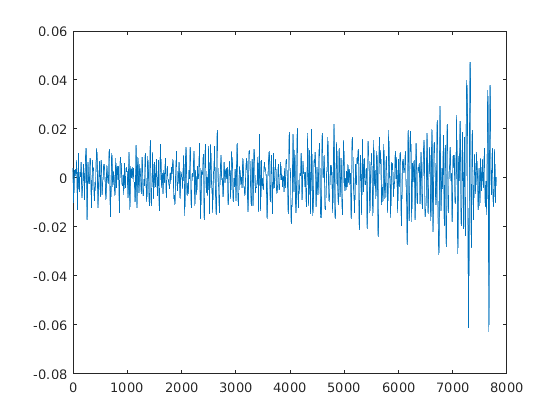

clf
plot(t, imf_eemd(:,10))

%xlim([0,450])

plot(t, imf_eemd(:,10))